# Lab 10 FIR Filter Design

### ### Insert Name ###

**Note: Run sections independently (i.e., click on Run Section, not on Run)**

## Clear Workspace

close all
clear

load lab10dat.mat

## Lab Activity, Item 1:  Truncated ideal low-pass filter

% Impulse response

N = 400; %<- Uncomment and complete
fm = .0204; %<- Uncomment and complete

% Make sure TruncIdlLPF.m is in your Lab10 folder 
htrunc = TruncId1LPF(N,fm);

htrunc(213)

ans = 0.0265


figure
stem(0:400,htrunc)
xlabel('n')
ylabel('htrunc[n]')
title('Impulse response: Truncated Ideal LP')

% Frequency response
FS = 20000

FS = 20000

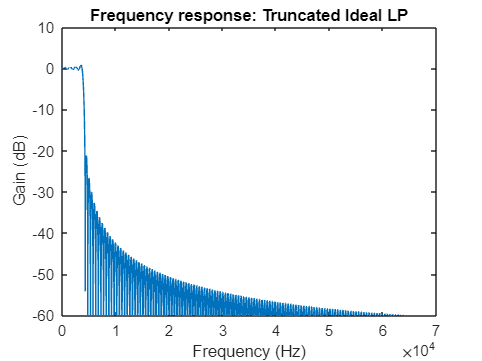


[Htrunc,f] = freqz(htrunc,1,20000,Fs);%<- Uncomment and complete

figure
plot(f,20*log10(abs(Htrunc)))
ylim([-60,10])
xlabel('Frequency (Hz)')
ylabel('Gain (dB)')
title('Frequency response: Truncated Ideal LP')

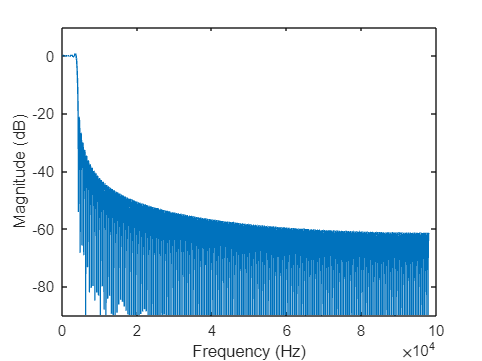


plot(f,20*log10(abs(Htrunc)))
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
ylim([-90,10])

## Lab Activity, Item 2: Minimax filter design

% Impulse response

N = 400; %<- Uncomment and complete
fm = 4/196.078; %<- Uncomment and complete
delta = 1/196.078; %<- Uncomment and complete


frqs = [0 fm  fm+delta 0.5]*2;
amp = [1 1 0 0];

hpm = firpm(N, frqs, amp); %<- Uncomment and complete

hpm(213)

ans = 0.0261

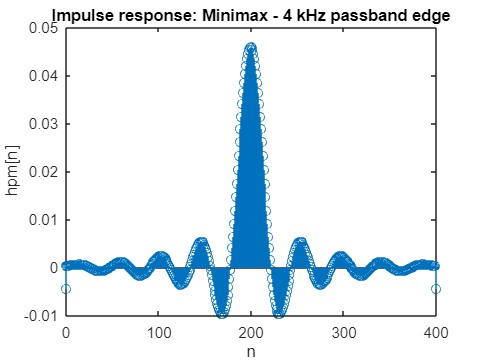


figure
stem(0:400,hpm)
xlabel('n')
ylabel('hpm[n]')
title('Impulse response: Minimax - 4 kHz passband edge')

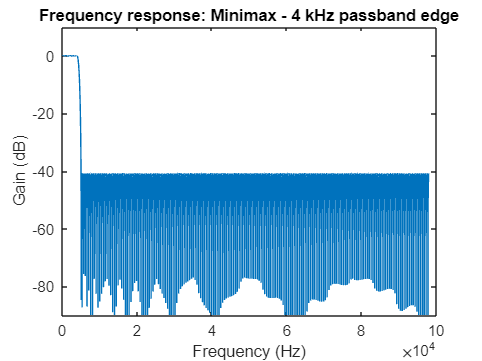

x = 0.5000 + 0.5000i

ans = 0.7071

ans = 0.7854

k = 1

N = 18

x = -3.6454 + 1.3268i

ans = 2.7925

f = 0.0313

x = -0.2551 - 0.6159i

ans = 0.6667

ans = -1.9635

% Frequency response

[Hpm,f] = freqz(hpm,1,20000,Fs); %<- Uncomment and complete

figure
plot(f,20*log10(abs(Hpm)))
ylim([-90,10])
xlabel('Frequency (Hz)')
ylabel('Gain (dB)')
title('Frequency response: Minimax - 4 kHz passband edge')

## Lab Assignment, Item 1:

### Spectrum of demodulated signal before filtering (positive frequencies)

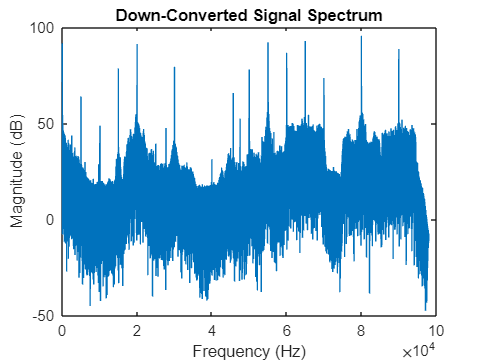

X = abs(fftshift(fft(x_b)));
L = length(x_b);

freq_x = ((-(L-1)/2):(L-1)/2)*Fs/L;

figure
plot(freq_x((L+1)/2:end), 20*log10(X((L+1)/2:end)))
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Down-Converted Signal Spectrum')

### Play demodulated signal

% Without low-pass filter
soundsc(x_b,Fs)


## Part(i): Compare 2 Low-Pass Filter Designs 

##  Play demodulated, filtered signals

% Using htrunc to low-pass:

ytrunc = filter(htrunc,1,x_b); %<- Uncomment and complete

% Play filtered signal
soundsc(ytrunc,Fs) 

% Using hpm to low-pass:

ypm = filter(hpm,1,x_b); %<- Uncomment and complete

% Play filtered signal
soundsc(ypm,Fs) 

**Notes on the differences you hear in the musical output (for your personal reference only):**

- The audio with the low-pass filter seems much more faded and kind of quieter with a little bit of fading in and out while the minimax is a little more clear and less faded with a more constant sound.

## Part(ii): Compare 3 Passbands for the Minimax Filter

### Design additional filter with passband edge of 2 kHz

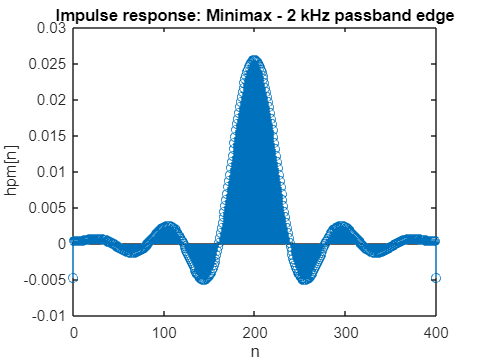

% Hint: Check the section 'Lab Activity, Item 2: Minimax filter design' above 
N = 400; %<- Uncomment and complete
fm = 2/196.078; %<- Uncomment and complete
delta = 1/196.078; %<- Uncomment and complete

frqs = [0 fm  fm+delta 0.5]*2;
amp = [1 1 0 0];

hpm2 = firpm(N, frqs, amp); %<- Uncomment and complete

figure
stem(0:400,hpm2)
xlabel('n')
ylabel('hpm[n]')
title('Impulse response: Minimax - 2 kHz passband edge')

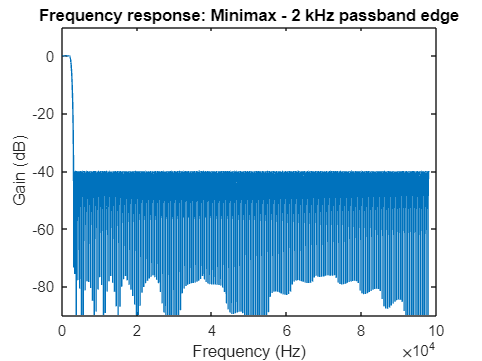


[Hpm2,f] = freqz(hpm2,1,20000,Fs); %<- Uncomment and complete

figure
plot(f,20*log10(abs(Hpm2)))
ylim([-90,10])
xlabel('Frequency (Hz)')
ylabel('Gain (dB)')
title('Frequency response: Minimax - 2 kHz passband edge')

### Design additional filter with passband edge of 6 kHz

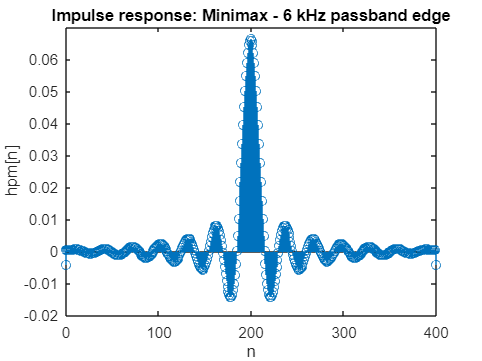

% Hint: Check the section 'Lab Activity, Item 2: Minimax filter design' above 
N = 400; %<- Uncomment and complete
fm = 6/196.078; %<- Uncomment and complete
delta = 1/196.078; %<- Uncomment and complete

frqs = [0 fm  fm+delta 0.5]*2;
amp = [1 1 0 0];

hpm6 = firpm(N, frqs, amp); %<- Uncomment and complete

figure
stem(0:400,hpm6)
xlabel('n')
ylabel('hpm[n]')
title('Impulse response: Minimax - 6 kHz passband edge')

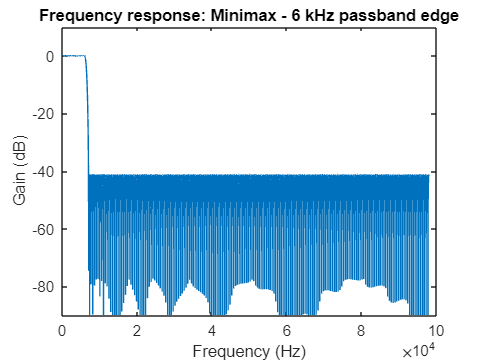


[Hpm6,f] = freqz(hpm6,1,20000,Fs); %<- Uncomment and complete

figure
plot(f,20*log10(abs(Hpm6)))
ylim([-90,10])
xlabel('Frequency (Hz)')
ylabel('Gain (dB)')
title('Frequency response: Minimax - 6 kHz passband edge')

###  Play demodulated, filtered signals

% Using hpm2 to low-pass:

y2 = filter(hpm2,1,x_b);%<- Uncomment and complete

% Play filtered signal
soundsc(y2,Fs)

% Using hpm6 to low-pass:

y6 = filter(hpm6,1,x_b);%<- Uncomment and complete

% Play filtered signal
soundsc(y6,Fs)

**Notes on the differences you hear in the musical output (for your personal reference only):**

### Contrast the two filters

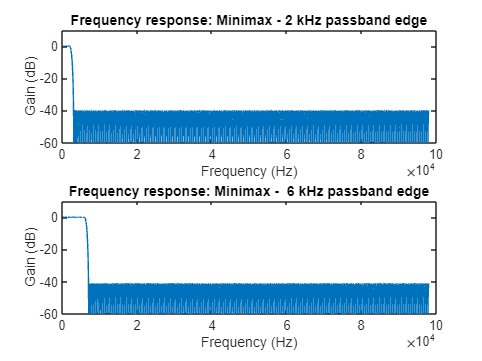

% Frequency response

[Hpm2,f] = freqz(hpm2,1,20000,Fs); %<- Uncomment and complete

figure
subplot(2,1,1)
plot(f,20*log10(abs(Hpm2)))
ylim([-60,10])
xlabel('Frequency (Hz)')
ylabel('Gain (dB)')
title('Frequency response: Minimax - 2 kHz passband edge')

[Hpm6,f] = freqz(hpm6,1,20000,Fs); %<- Uncomment and complete

subplot(2,1,2)
plot(f,20*log10(abs(Hpm6)))
ylim([-60,10])
xlabel('Frequency (Hz)')
ylabel('Gain (dB)')
title('Frequency response: Minimax -  6 kHz passband edge')

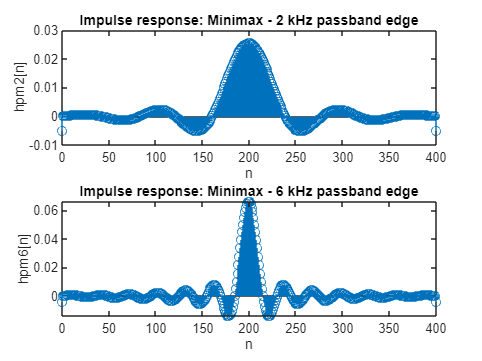

% Impulse response

figure
subplot(2,1,1)

stem(0:400,hpm2)
xlabel('n')
ylabel('hpm2[n]')
title('Impulse response: Minimax - 2 kHz passband edge')

subplot(2,1,2)
stem(0:400,hpm6)
xlabel('n')
ylabel('hpm6[n]')
title('Impulse response: Minimax - 6 kHz passband edge')